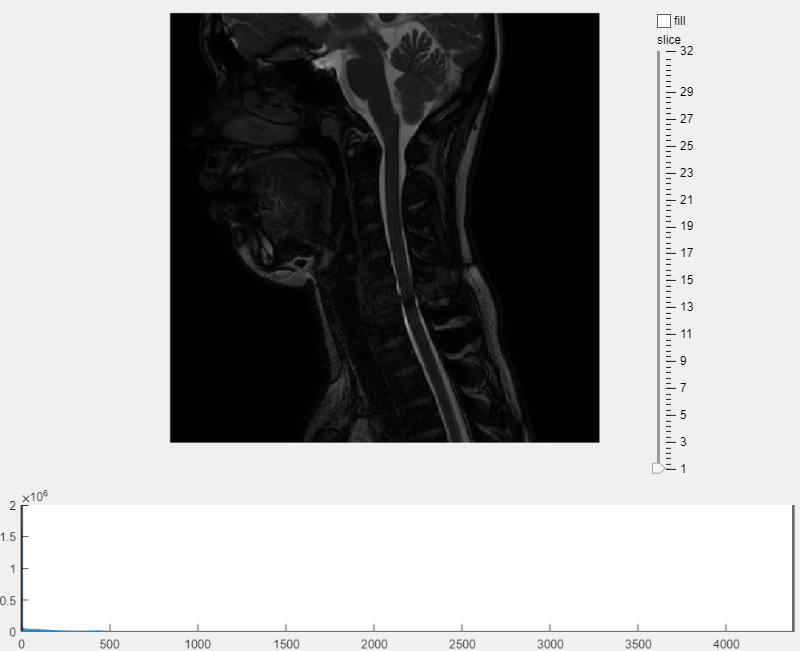

clc
dcmHandler = scripts.dicomHandler.DICOMHandler();
dcmHandler.readDICOMDIR();
[dcmInfo, dcmImg] = dcmHandler.getPreview();
imgWidth = dcmInfo.Rows;
imgHeight = dcmInfo.Columns;
dcmImgs = dcmHandler.readAllImage();
imgViewer = scripts.imageViewer.guiImageViewer( ...
    "image3D", dcmImgs, ...
    "imageWidth", imgWidth, ...
    "imageHeight", imgHeight);

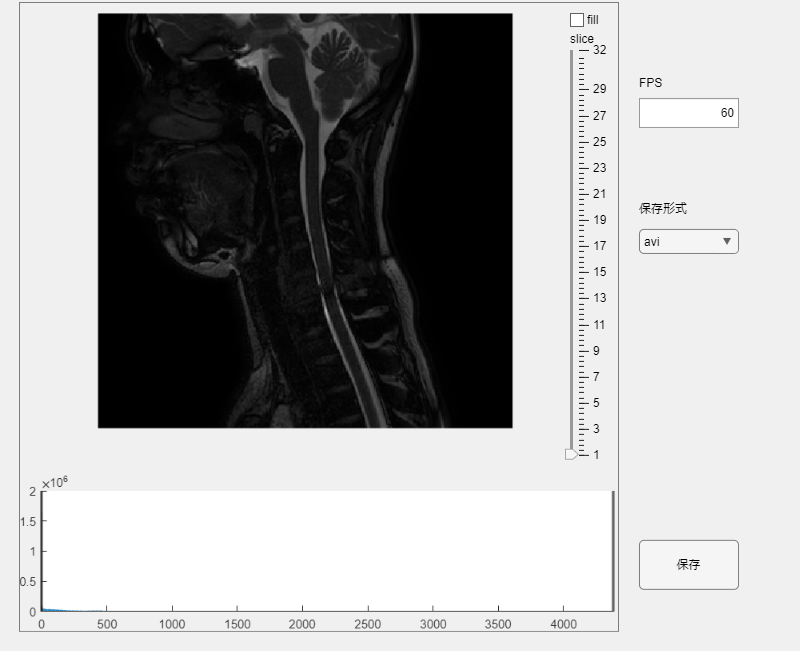

movieConverter("imageViewerObj", imgViewer);